# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## About This Tutorial

This tutorial describes storage of hypothetical data from extracellular electrophysiology experiments in NWB for the following data categories:

- Raw voltage recording

- Local field potential (LFP) and filtered electrical signals

- Spike times

## Before You Begin

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

**Important**: The dimensions of timeseries data in MatNWB should be defined in the opposite order of how it is defined in the nwb-schemas. In NWB, time is always stored in the first dimension of the data, whereas in MatNWB time should be stored in the last dimension of the data. This is explained in more detail here: [MatNWB <-> HDF5 Dimension Mapping](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/dimensionMapNoDataPipes.html).

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a `session_description`, `identifier`, and `session_start_time`. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object these required fields along with any additional metadata. In MatNWB, arguments are specified using MATLAB's keyword argument pair convention, where each argument name is followed by its value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.7.0'
                                        file_create_date: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: {[2018-04-25T02:30:03.000000+02:00]}
                               timestamps_reference_time: {[2018-04-25T03:00:45.000000+02:00]}
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 types.untyped.Set]
                          general_expe

## Electrode Information

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: `x`, `y`, `z`, `impedance`, `location`, `filtering`, and `electrode_group`.

### Electrodes Table

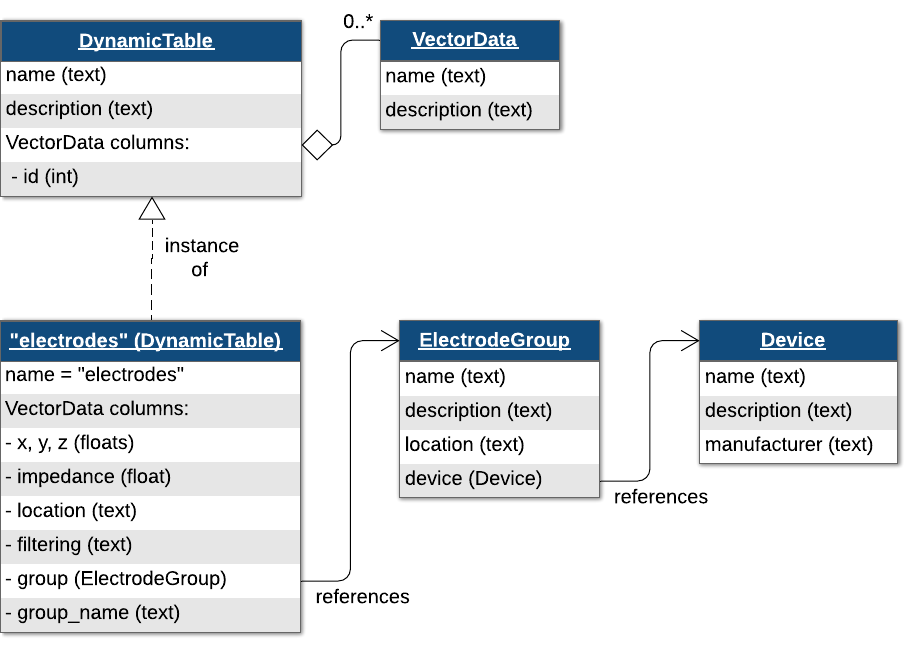

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

numShanks = 4;
numChannelsPerShank = 3;
numChannels = numShanks * numChannelsPerShank;

electrodesDynamicTable = types.hdmf_common.DynamicTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', device);
for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    electrodeGroup = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, electrodeGroup);
    for iElectrode = 1:numChannelsPerShank
        electrodesDynamicTable.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(electrodeGroup), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
electrodesDynamicTable.toTable() % Display the table

ans = 12×5 table
    id     location                 group                group_name            label        
    __    ___________    ____________________________    __________    _____________________

     0    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode1'}
     1    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode2'}
     2    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode3'}
     3    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode1'}
     4    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode2'}
     5    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode3'}
     6    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3'} 

nwb.general_extracellular_ephys_electrodes = electrodesDynamicTable;

### Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is a construct that enables linking one neurodata type to another, allowing a neurodata type to reference another within the NWB file.

## Recorded Extracellular Signals

Voltage data are stored using the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) class, a subclass of the [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) class specialized for voltage data. 

### Referencing Electrodes

In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we first need to reference a set of rows in the `electrodes` table to indicate which electrode (channel) each entry in the electrical series were recorded from. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, using row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrodesDynamicTable), ...
    'description', 'all electrodes', ...
    'data', (0:length(electrodesDynamicTable.id.data)-1)');

### Raw Voltage Data

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

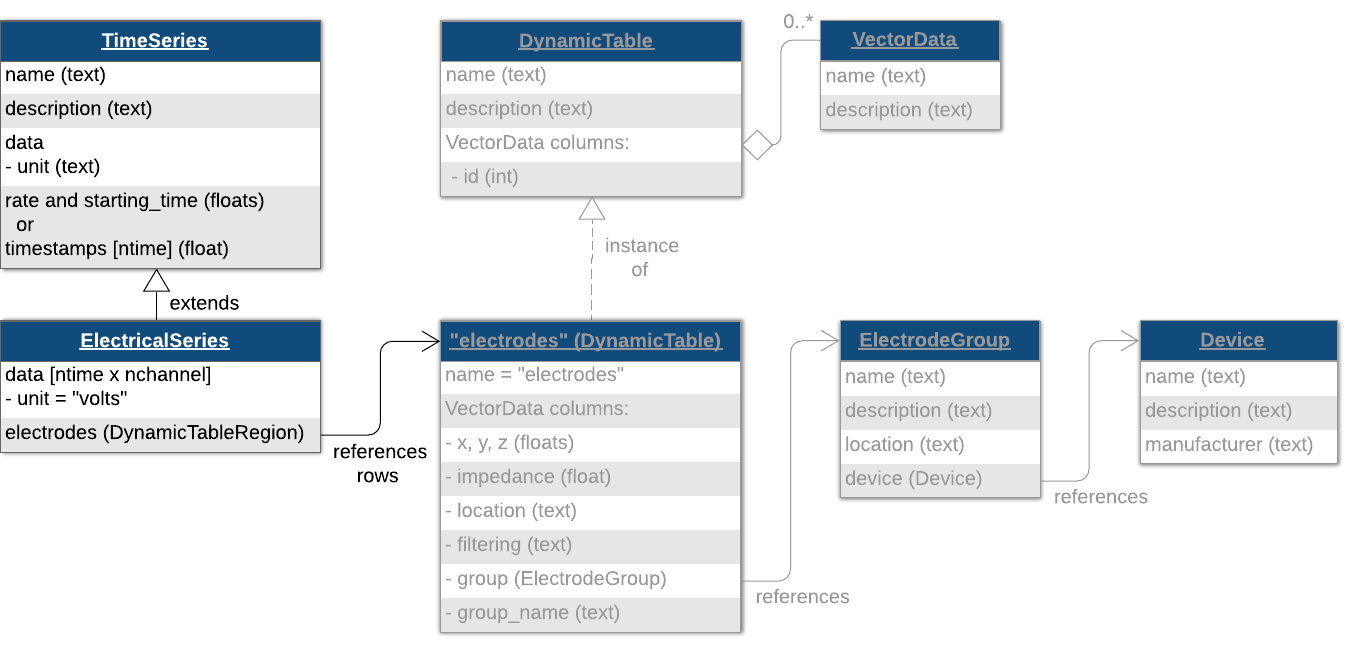

raw_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(numChannels, 3000), ... % nChannels x nTime
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group.

nwb.acquisition.set('ElectricalSeries', raw_electrical_series);

## Processed Extracellular Electrical Signals

### LFP

LFP refers to data that has been low-pass filtered, typically below 300 Hz. This data may also be downsampled. Because it is filtered and potentially resampled, it is categorized as processed data. LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, we store it inside an [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) object and then place the [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` in the [behavior](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/behavior.html) tutorial

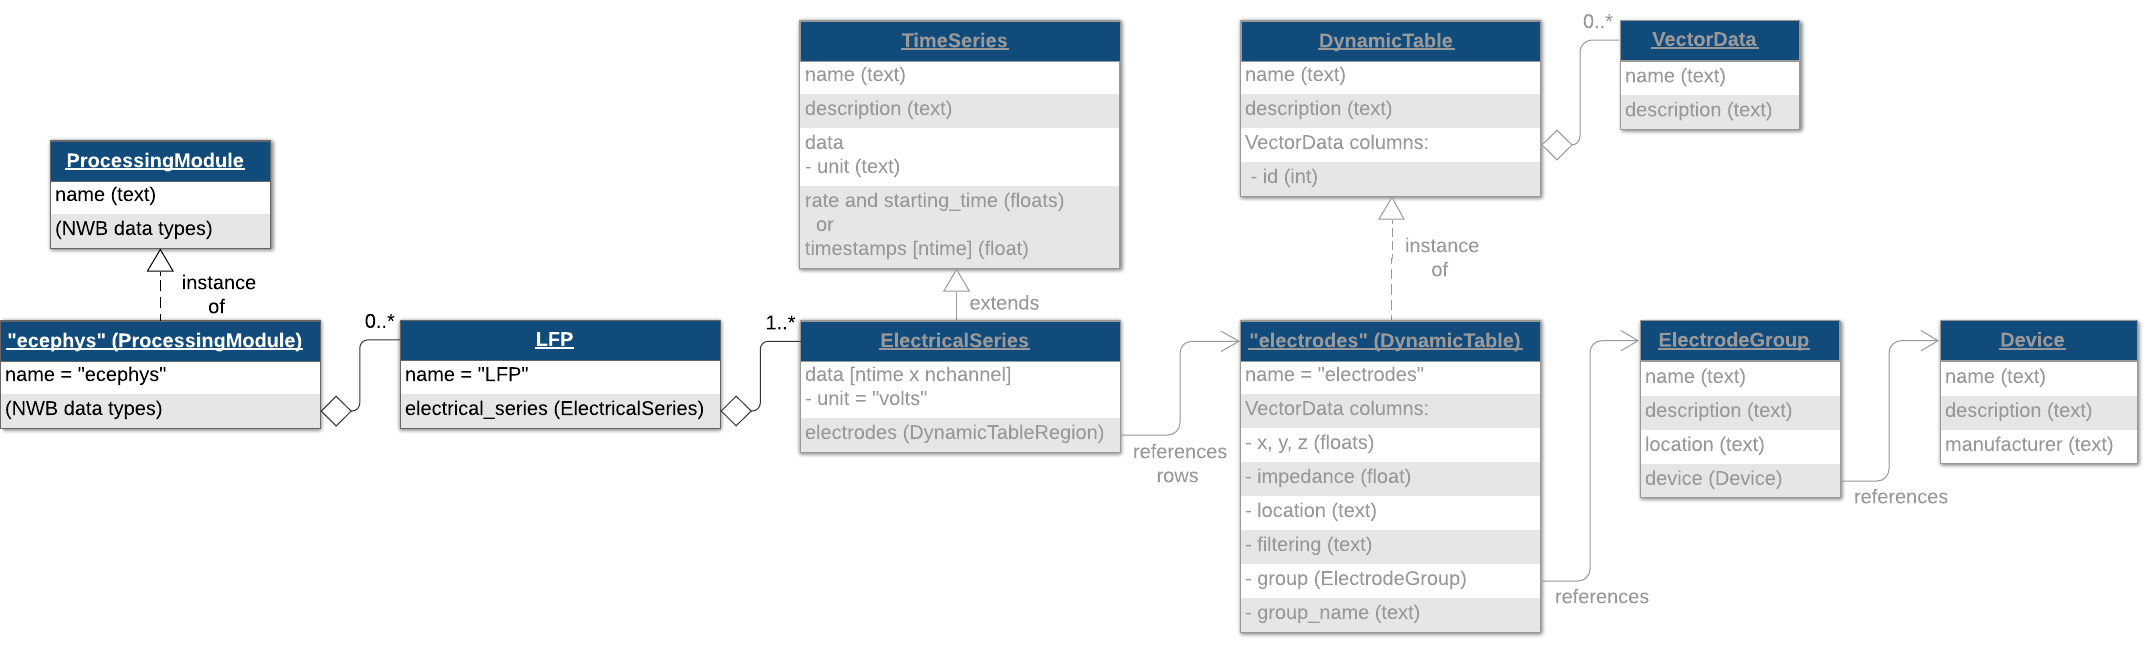

lfp_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(numChannels, 100), ... nChannels x nTime
    'filtering', 'Low-pass filter at 300 Hz', ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', lfp_electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

### Other Types of Filtered Electrical Signals

If your derived data is filtered for frequency ranges other than LFP—such as Gamma or Theta—you should store it in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) and encapsulate it within a [`FilteredEphys`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FilteredEphys.html) object instead of the [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) object.

% Generate filtered data
filtered_data = randn(50, 12); % 50 time points, 12 channels
filtered_data = permute(filtered_data, [2, 1]); % permute timeseries for matnwb

% Create an ElectricalSeries object
filtered_electrical_series = types.core.ElectricalSeries( ...
    'description', 'Data filtered in the Theta range', ...
    'data', filtered_data, ...
    'electrodes', electrode_table_region, ...
    'filtering', 'Band-pass filtered between 4 and 8 Hz', ...
    'starting_time', 0.0, ...
    'starting_time_rate', 200.0 ...
    );

% Create a FilteredEphys object and add the filtered electrical series
filtered_ephys = types.core.FilteredEphys();
filtered_ephys.electricalseries.set('FilteredElectricalSeries', filtered_electrical_series);

% Add the FilteredEphys object to the ecephys module
ecephys_module.nwbdatainterface.set('FilteredEphys', filtered_ephys);

## Spike Times and Extracellular Events

### Sorted Spike Times

Spike times are stored in a [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table, a specialization of the [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) class. The default [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table is located at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials` (see [convertTrials](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/convertTrials.html)). Here, we generate some random spike data and populate the table. 

num_cells = 10;
spikes = cell(1, num_cells);
for iShank = 1:num_cells
    spikes{iShank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.7889 0.1248 0.0928 0.2707 0.1974 0.6140 0.5269 0.8578 0.2521 0.3357 0.5645 0.6261 0.3689 0.1525 0.9083 0.0096 0.0596 0.4523 0.7600 0.7621 0.6994 0.6525 0.2453]}    {[0.7645 0.5819 0.6682 0.7258 0.5179 0.0216 0.8548 0.1432 0.6627 0.2701 0.0775 0.7737 0.0955 0.0822 0.5690 0.8399 0.9168 0.8381 0.2430 0.7348 0.1093 0.6960 0.5646 0.7789]}    {[0.2669 0.1974 0.5509 0.6352 0.9233 0.2397 0.1551 0.1059 0.0309 0.4465 0.7234 0.3476 0.7493 0.2728 0.3785 0.8800 0.1594 0.9824 0.8824 0.9872 0.7294 0.2122 0.3854 0.6242 0.7033]}    {[0.0305 0.1482 0.9007 0.9969 0.3330 0.1412 0.2632 0.9874 0.2263 0.4062 0.1271 0.0930 0.5340 0.9745 0.3802 0.7584 0.0886 0.7761 0.7629 0.6781 0.5738 0.9735 0.9204 0.6316 0.1990 0.3121 0.8357]}    {[0.4695 0.4346 0.1296 0.8760 0.2823 0.8395 0.5729 0.9154 0.3922 0.5554 0.5056 0.7846 0.6742 0.0867 0.6670 0.8835 0.7409 0.3300 0.8304 0.6126 0.6184 0.0431 0.6866]}    {[0.3974 0.8695 0.0133 0.8423 0.9780 0.0408 0.6209 0.3603 0.1148 0.7581 0.8336 0.1

#### Ragged Arrays

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. These indexed columns have two components, the [**VectorData**](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/VectorData.html) object that holds the data and the [**VectorIndex**](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/VectorIndex.html) object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects. For more information about ragged arrays, we refer you to the **"Ragged Array Columns"** section of the [dynamic table](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/dynamic_tables.html) tutorial.

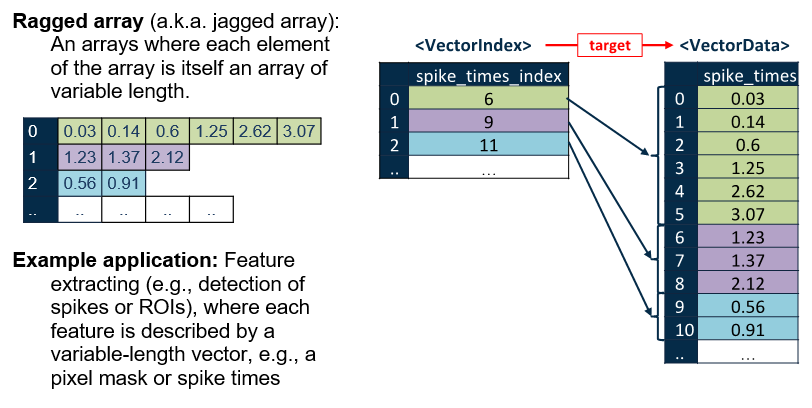

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

nwb.units.toTable

ans = 10×2 table
    id     spike_times 
    __    _____________

     1    {23×1 double}
     2    {24×1 double}
     3    {25×1 double}
     4    {27×1 double}
     5    {23×1 double}
     6    {21×1 double}
     7    {27×1 double}
     8    {27×1 double}
     9    {28×1 double}
    10    {28×1 double}


### Unsorted Spike Times

While the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table is used to store spike times and waveform data for spike-sorted, single-unit activity, you may also want to store spike times and waveform snippets of unsorted spiking activity. This is useful for recording multi-unit activity detected via threshold crossings during data acquisition. Such information can be stored using [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

% In the SpikeEventSeries the dimensions should be ordered as 
% [num_events, num_channels, num_samples].
% Define spike snippets: 20 events, 3 channels, 40 samples per event. 
spike_snippets = rand(20, 3, 40);
% Permute spike snippets (See dimensionMapNoDataPipes tutorial)
spike_snippets = permute(spike_snippets, [3,2,1]) 

spike_snippets = spike_snippets(:,:,1) =

    0.2780    0.0148    0.4113
    0.9089    0.2536    0.2512
    0.2961    0.4550    0.8541
    0.5709    0.1663    0.1813
    0.6639    0.8085    0.9136
    0.1532    0.5275    0.1305
    0.5169    0.6597    0.9037
    0.6069    0.9045    0.9244
    0.9657    0.3104    0.8828
    0.4293    0.2333    0.9000
    0.3021    0.8831    0.9400
    0.1023    0.8102    0.2832
    0.5171    0.9477    0.6370
    0.6029    0.9545    0.8187
    0.5206    0.4737    0.8799
    0.3451    0.1380    0.5775
    0.0495    0.1734    0.9920
    0.8352    0.1176    0.1876
    0.8302    0.8044    0.6006
    0.3333    0.6354    0.1640
    0.1174    0.6743    0.8681
    0.3170    0.6718    0.1311
    0.6166    0.2288    0.7316
    0.8783    0.7603    0.0001
    0.2442    0.5209    0.2155
    0.3402    0.2235    0.5329
    0.5665    0.0798    0.7609
    0.5323    0.5660    0.5499
    0.7377    0.0673    0.3152
    0.2693    0.4380    0.2733
    0.9295    0.5399    0.44


% Create electrode table region referencing electrodes 0, 1, and 2
shank0_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrodesDynamicTable), ...
    'description', 'shank0', ...
    'data', (0:2)');

% Define spike event series for unsorted spike times
spike_events = types.core.SpikeEventSeries( ...
    'data', spike_snippets, ...
    'timestamps', (0:19)', ...  % Timestamps for each event
    'description', 'events detected with 100uV threshold', ...
    'electrodes', shank0_table_region ...
);

% Add spike event series to NWB file acquisition
nwb.acquisition.set('SpikeEvents_Shank0', spike_events);

### Detected Events

If you need to store the complete, continuous raw voltage traces, along with unsorted spike times, you should store the traces in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in the acquisition group, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class to identify the spike events in your raw traces.

% Create the EventDetection object
event_detection = types.core.EventDetection( ...
    'detection_method', 'thresholding, 1.5 * std', ...
    'source_electricalseries', types.untyped.SoftLink(raw_electrical_series), ...
    'source_idx', [1000; 2000; 3000], ...
    'times', [.033, .066, .099] ...
);

% Add the EventDetection object to the ecephys module
ecephys_module.nwbdatainterface.set('ThresholdEvents', event_detection);

### Storing Spike Features (e.g Principal Components)

NWB also provides a way to store features of spikes, such as principal components, using the [`FeatureExtraction`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FeatureExtraction.html) class. 

% Generate random feature data (time x channel x feature)
features = rand(3, 12, 4); % 3 time points, 12 channels, 4 features
features = permute(features, [3,2,1]) % reverse dimension order for matnwb

features = features(:,:,1) =

    0.9316    0.4439    0.1664    0.8142    0.2697    0.6258    0.4445    0.5889    0.5936    0.5510    0.3843    0.0928
    0.6321    0.6096    0.2896    0.5378    0.2169    0.2326    0.6727    0.3081    0.5352    0.3272    0.3730    0.7105
    0.5674    0.5495    0.8397    0.5804    0.3298    0.0668    0.6826    0.1170    0.2237    0.8309    0.8602    0.1544
    0.4657    0.4697    0.6416    0.8899    0.2070    0.2748    0.1939    0.7873    0.9721    0.7856    0.0667    0.1039


features(:,:,2) =

    0.9188    0.8798    0.8666    0.2478    0.7362    0.0880    0.0963    0.1304    0.5751    0.4159    0.8664    0.6476
    0.9597    0.7697    0.0909    0.7685    0.0993    0.9162    0.8964    0.5880    0.4342    0.1795    0.7080    0.4490
    0.5198    0.6699    0.2718    0.2714    0.3393    0.5473    0.2908    0.5508    0.2389    0.9618    0.6670    0.1449
    0.1393    0.5076    0.7794    0.9437    0.9352    0.1637    0.5838    0.1138    0.7266    0.7907  


% Create the FeatureExtraction object
feature_extraction = types.core.FeatureExtraction( ...
    'description', {'PC1', 'PC2', 'PC3', 'PC4'}, ... % Feature descriptions
    'electrodes', electrode_table_region, ... % DynamicTableRegion referencing the electrodes table
    'times', [.033; .066; .099], ... % Column vector for times
    'features', features ...
);

% Add the FeatureExtraction object to the ecephys module (if required)
ecephys_module.nwbdatainterface.set('PCA_features', feature_extraction);

## Choosing NWB-Types for Electrophysiology Data (A Summary)

As mentioned above, [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects are meant for storing electrical timeseries data like raw voltage signals or processed signals like LFP or other filtered signals. In addition to the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) class, NWB provides some more classes for storing event-based electropysiological data. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) and the section on [Extracellular Physiology](https://nwb-schema.readthedocs.io/en/latest/format.html#extracellular-electrophysiology) in the "NWB Format Specification" for more details on using these objects.

For storing unsorted spiking data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the entire raw voltage traces, only the waveform ‘snippets’ surrounding spike events, you should use [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. The [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table can hold just the spike times of sorted units or, optionally, include additional waveform information. You can use the optional predefined columns `waveform_mean`, `waveform_sd`, and `waveforms` in the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table to store individual and mean waveform data.

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =    -0.0003   -1.3106    2.3180    0.0008    1.9394    1.7373   -1.1235   -0.1723   -0.7690    0.3233
   -2.7453    0.6558    0.7985   -0.7032   -0.1310    0.7679   -1.0497    2.1285    0.8362    0.3742
    0.7983    1.4374    0.1157    0.9797    0.2739   -1.4714   -2.2506    1.2310   -0.5585    0.0383
   -0.3854   -1.5432    1.3848    0.9771    1.1799   -0.3393   -1.3353   -1.6190    2.2322   -1.1545
   -0.9029   -1.5846   -0.5733   -0.1312   -1.0385   -0.9423   -0.2002   -0.9642   -0.4652   -1.5418



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.7889
    0.1248
    0.0928
    0.2707
    0.1974
    0.6140
    0.5269
    0.8578
    0.2521
    0.3357


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)